# Color Calibration

#### Author: Joelle Dowling

#### Date: Autumn 2020

This project model the spectral quantum efficiency of the Google Pixel 4a sensor channels.  It illustrates how to estimate the channels using measured spectral radiances from the MCC and the raw RGB data from the MCC. 

We learned a number of things from this exercise.  

This will be achieved by using spectral radiance measurements and camera images for three different illuminants, tungsten (A), cool white fluorescent (cwf), and daylight (day).

## Start ISETCam

ieInit; % Initialize ISETCam

## Read the spectral radiance data

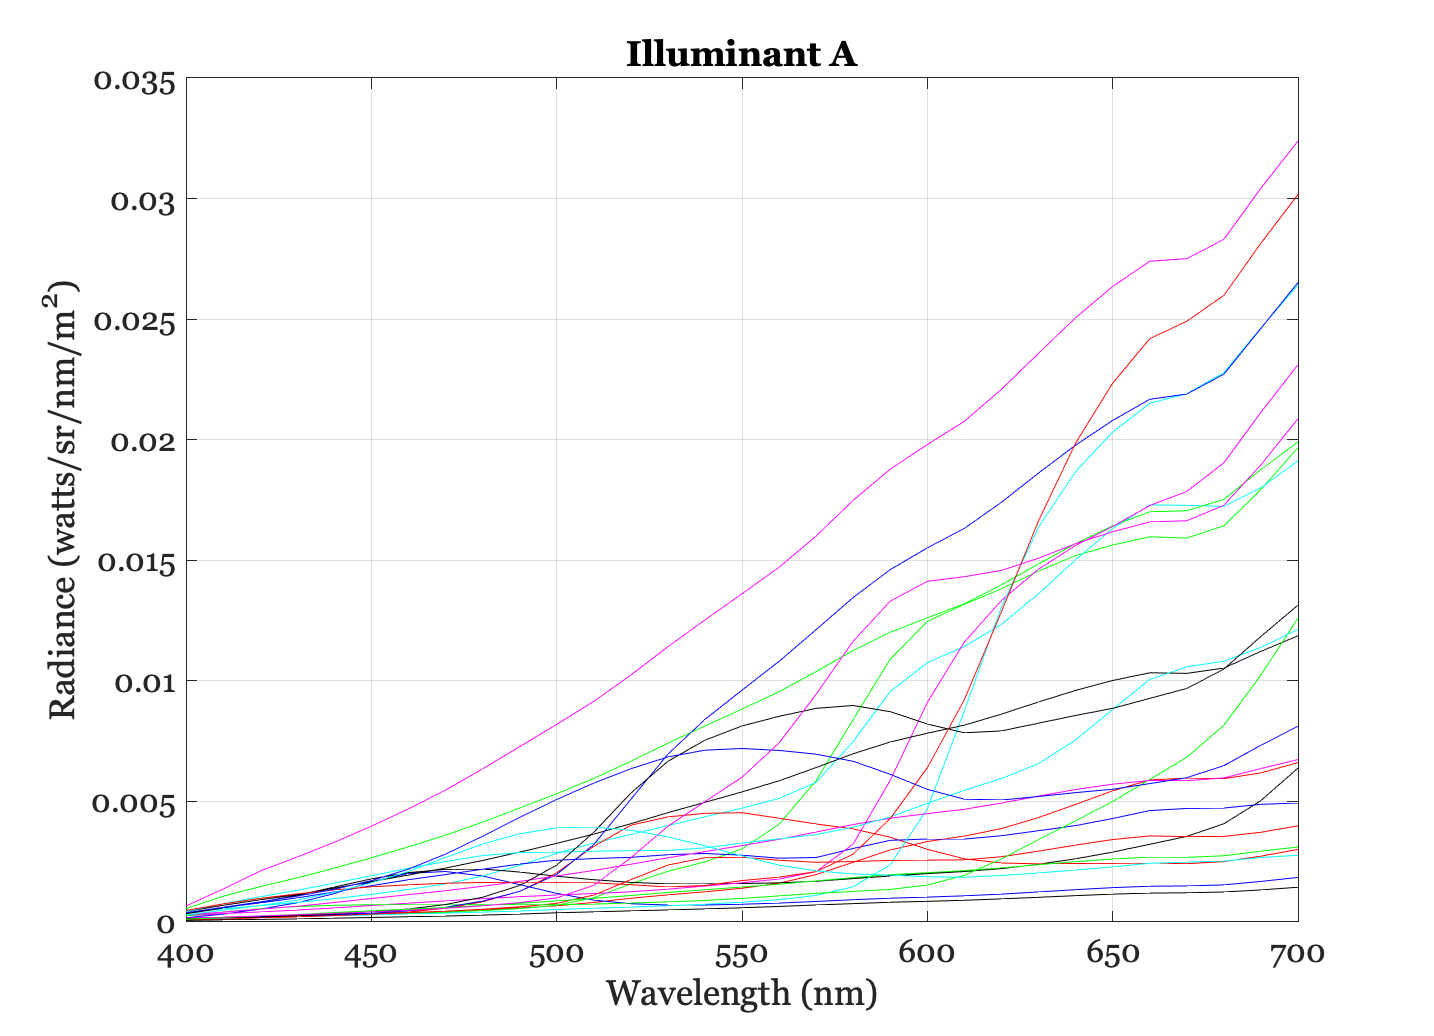

wavelength = 400:10:700;

% Set this to the directory where you have placed the radiance data
dataDir = '/Volumes/Wandell/Data Psych 221 Projects/Color calibration/Measurements 1/mccSpectralRadianceAndLights1';

fname = '20201023-mccRadianceData.mat';       % In psych221/projects
dataFile = fullfile(dataDir,fname);
radiance = ieReadSpectra(dataFile, wavelength);

radianceA   = radiance(:,1:24);
radianceCWF = radiance(:,25:48);
radianceDay = radiance(:,49:72);

plotRadiance(wavelength,radianceA);    title('Illuminant A');

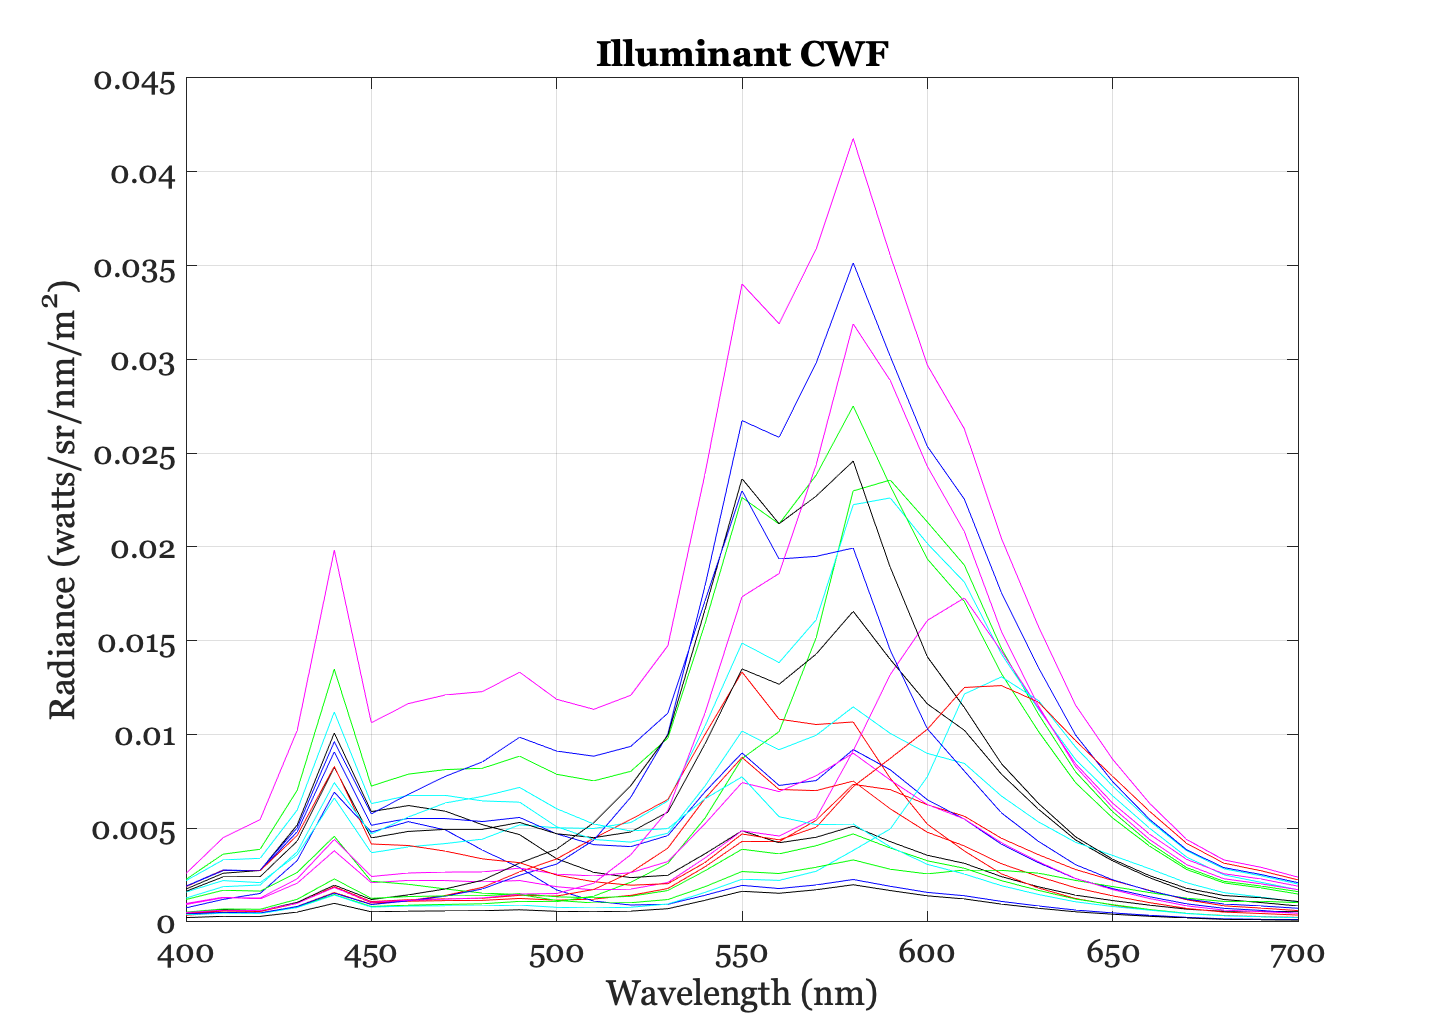

plotRadiance(wavelength,radianceCWF);  title('Illuminant CWF');

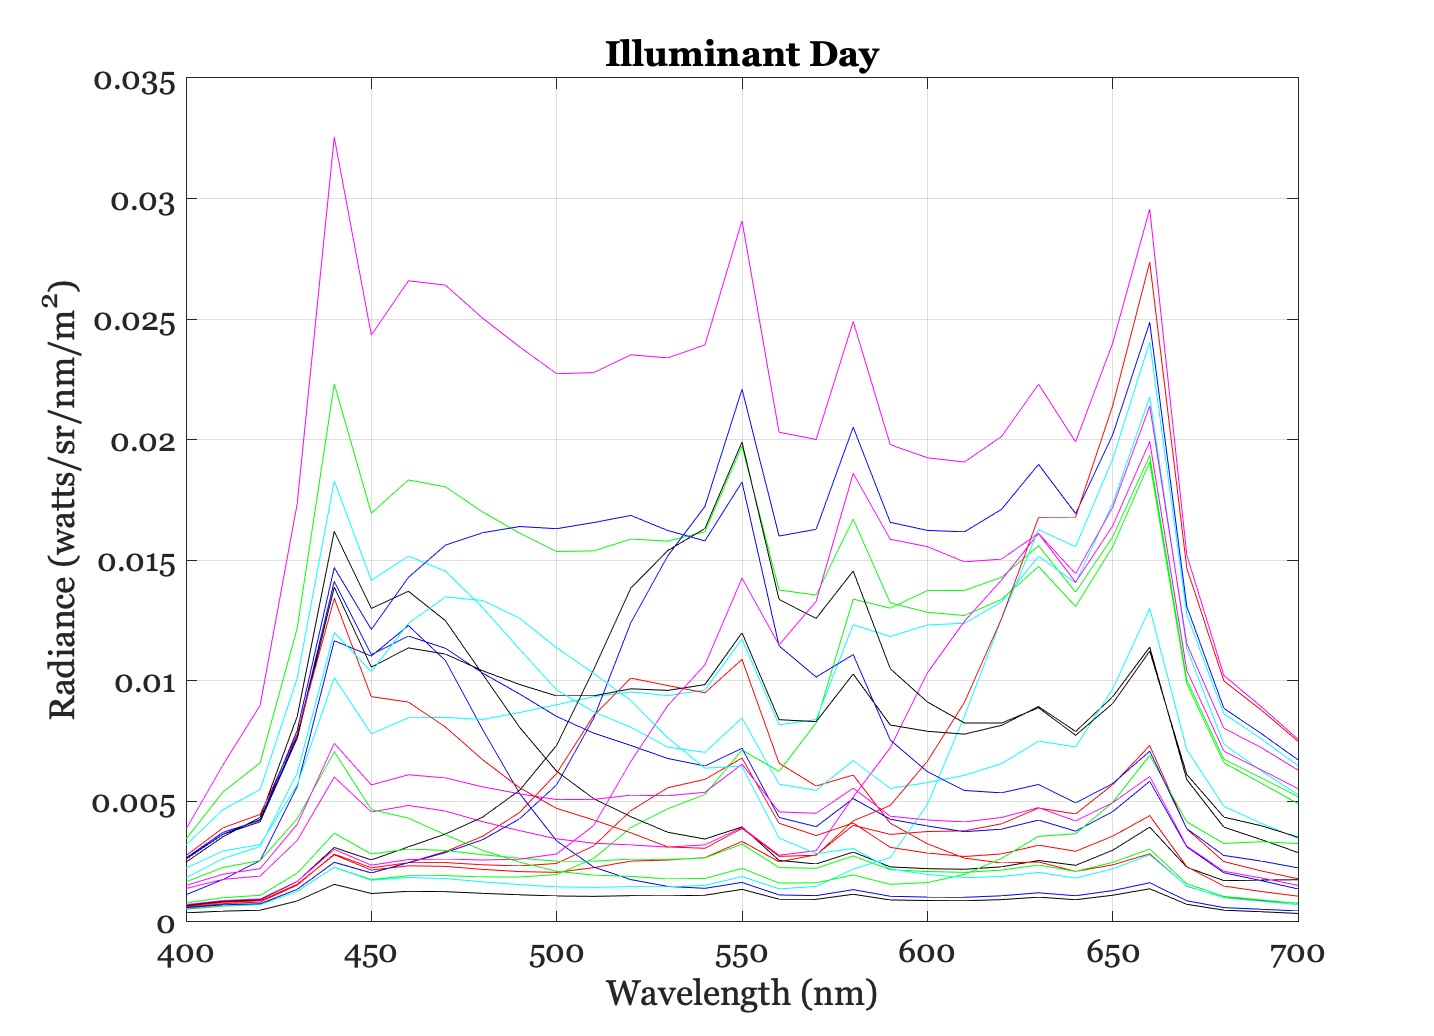

plotRadiance(wavelength,radianceDay);  title('Illuminant Day');

## Create an ISETCam sensor with the RGB values from Pixel 4 

% The location of your data may differ!
dataDir = fullfile(teachRootPath,'local','data','spectralqe','Measurements1','DNG-Illuminant-A');
camera_A = 'IMG_20201024_123128.dng'; % Sensor Data under illuminant A taken from Canvas
chdir(dataDir);

% Read a cropped version of the data into an ISETCam sensor
% The rectangle was selected separately in a preview to include the MCC.
thisRect = [1860  2010  350  255]; %col, row, width, height
[camera_A, info_A] = sensorDNGRead(camera_A,'crop',thisRect);
sensorWindow(camera_A);
% Select the corner points this way.
% cpA = chartCornerpoints(camera_A);   % Select corners
% {
cpA = [
    38   222
    316   224
    314    41
    40    40];
%}
blackBorder = true;  % Estimate rectangles
[rects, mLocs, pSize] = chartRectangles(cpA,4,6,0.5,blackBorder);

Black border


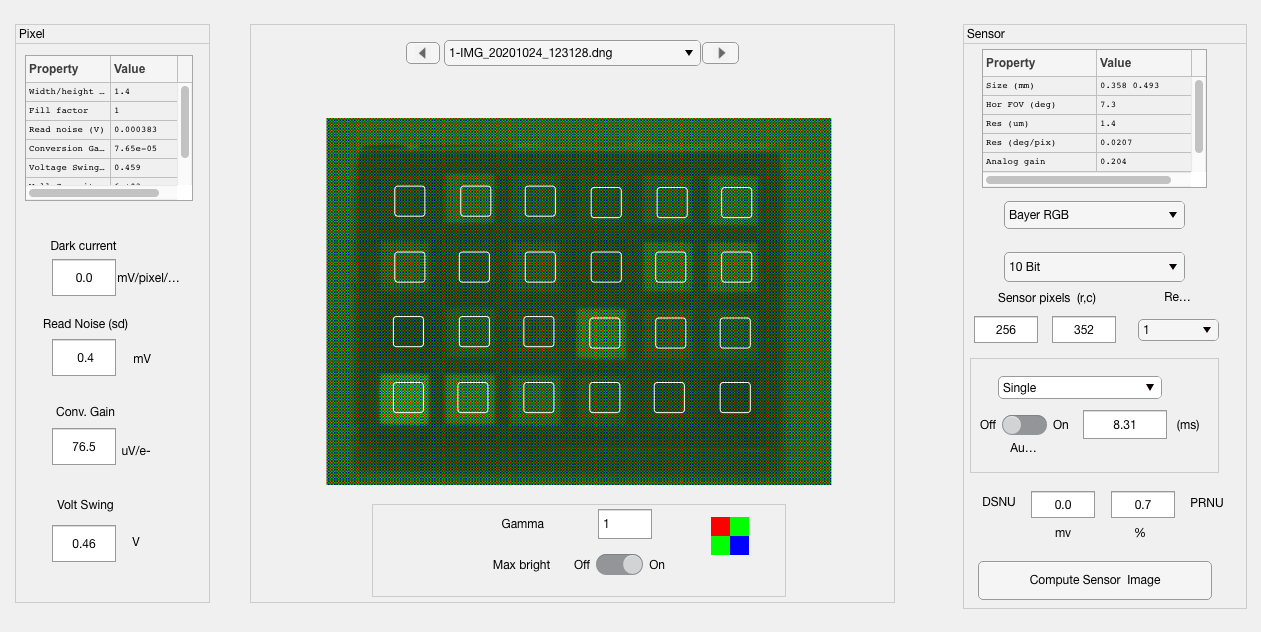

chartRectsDraw(camera_A,rects);  % Visualize the rectangles

#### Correct RGB values for Black Level and Exposure Time

% Get the values from each patch
nPixels = round(pSize(1)/4);  % Choose a fraction of the pixels in the patch
fullData = true;             % Return only the mean
dvalues = chartRectsData(camera_A,mLocs,nPixels,fullData,'dv'); %returns digital values
rgb_mean_A = zeros(24,3);
rgb_std_A = rgb_mean_A;
for ii = 1:24
    % Correct the values for the black level and exposure time
    theseValues = (dvalues{ii}- info_A.BlackLevel(1))./info_A.ExposureTime;
    rgb_mean_A(ii,:) = nanmean(theseValues);
    rgb_std_A(ii,:)  = nanstd(theseValues);
end

### We can get a sense of the signal to noise by plotting meanRGB / s.d. for each patch

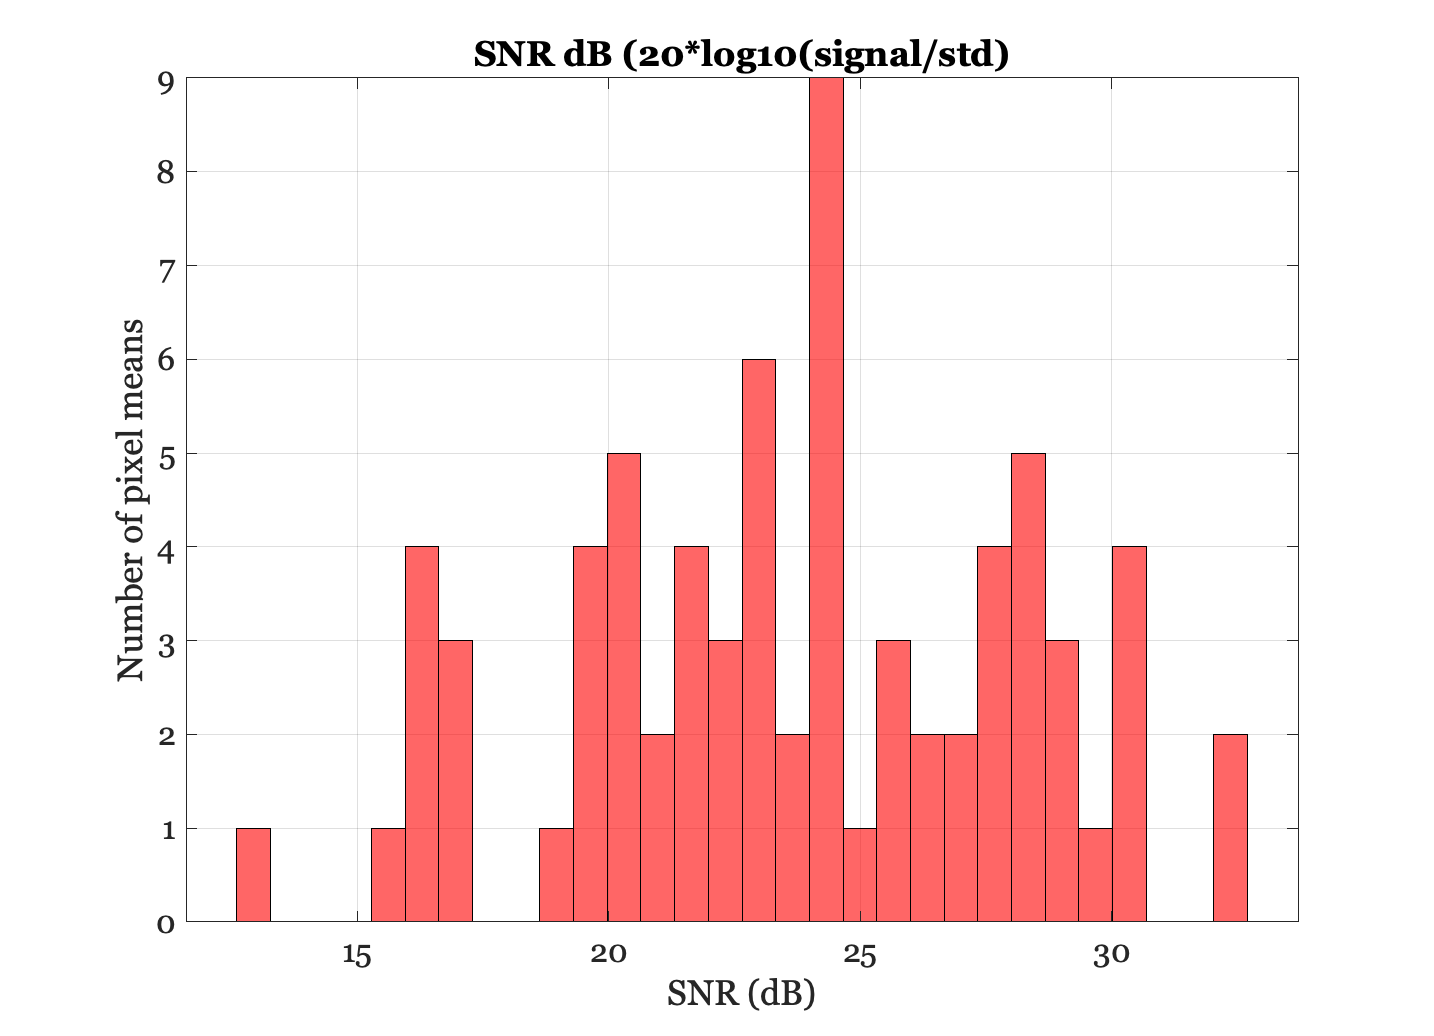

ieNewGraphWin;
histogram(log10(rgb_mean_A(:)./rgb_std_A(:))*20,30);
title('SNR dB (20*log10(signal/std)');
xlabel('SNR (dB)'); ylabel('Number of pixel means');
grid on;


% The typical noise to signal ratio is about 5 percent.
median(rgb_std_A(:)./rgb_mean_A(:))

ans = 0.0650

## Set up the linear equation

We are solving for spectral QE.  The radiance data are in the columns.  The RGB values for each patch are in the rows.  Here is the matrix formulation.


$$RGB = Radiance' * SpectralQE$$


The problem we are solving is that the spectral radiance data is not very complex.  In fact, the radiance data only spans a relatively small number of dimensions.  For example, there are 24 chips and yet, we are trying to solve for the spectral QE functions that have 31 wavelength samples.  Worse yet, many of the chips are basically the same (e.g., the gray series).  So, we are heavily under sampled to recover the 31 dimensional spectral quantum efficience.

Thus if we simply do this calculation, we get a bad result.

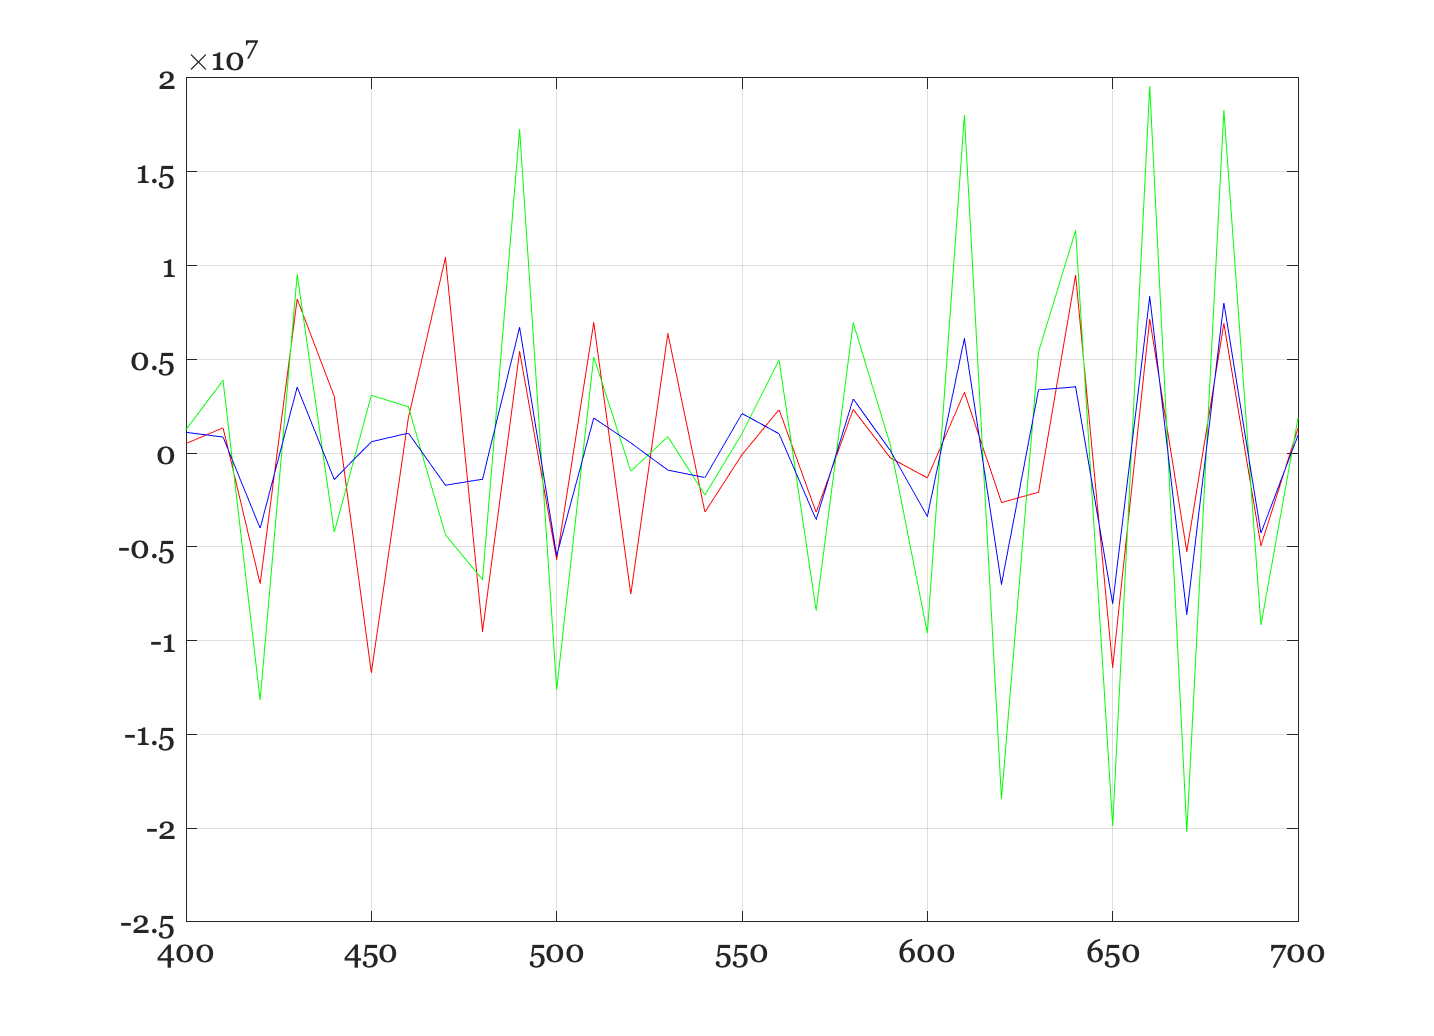

spectralQE = pinv(radianceA')*rgb_mean_A;
ieNewGraphWin;
plot(wavelength,spectralQE);
grid on;

The bad specalQE fits the data extremely well!  Overfitting!!!!

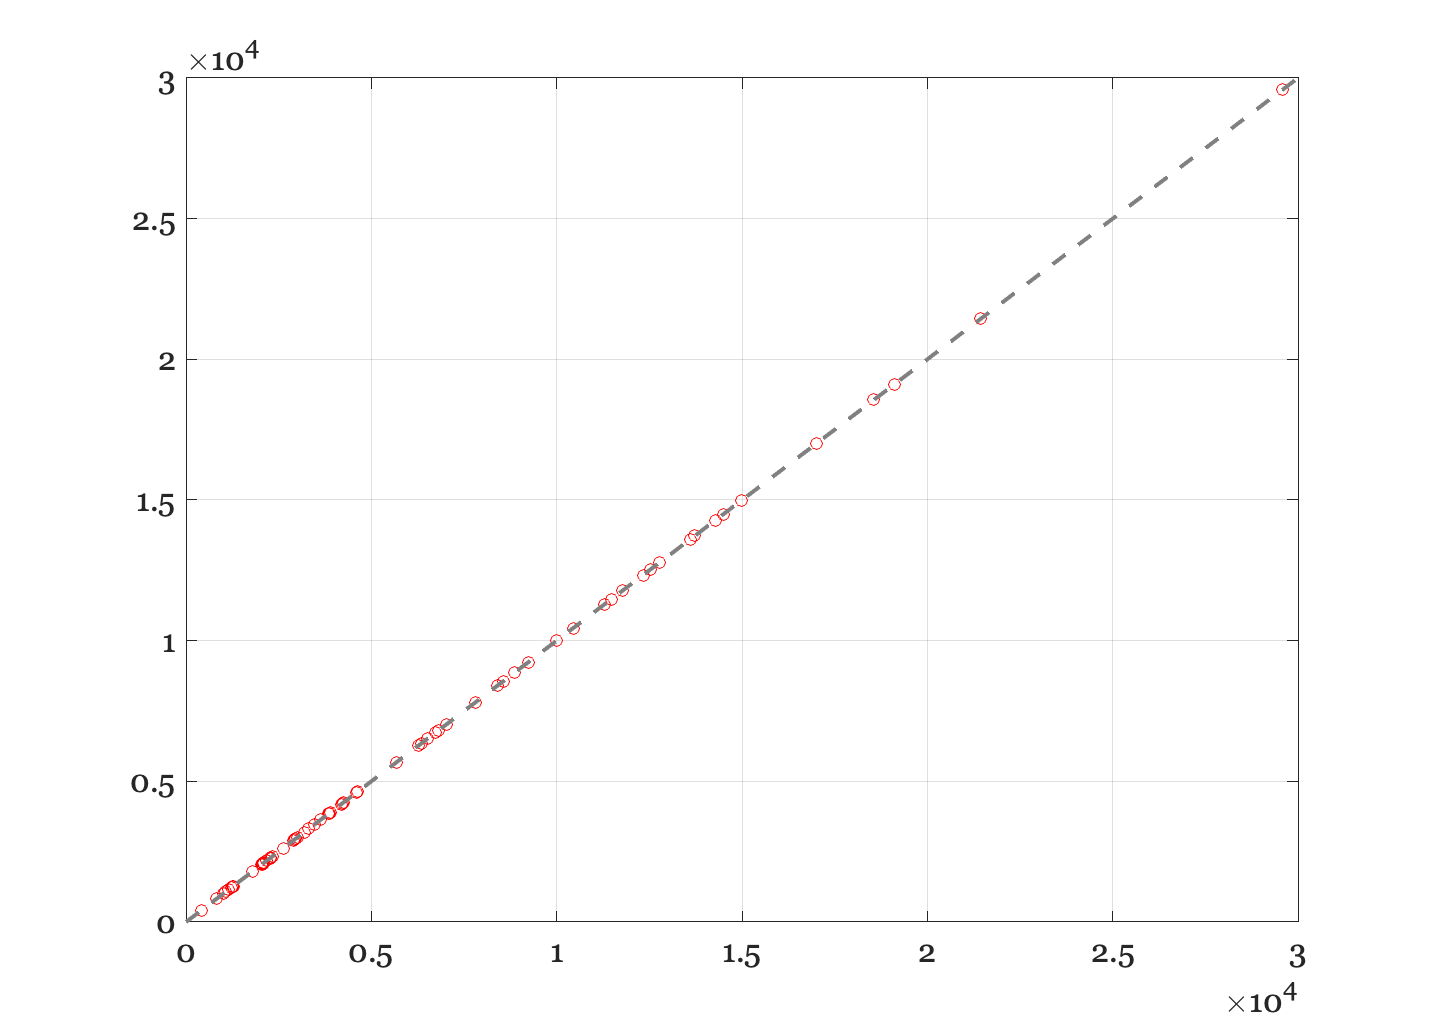

pred = radianceA'*spectralQE;
ieNewGraphWin;
plot(pred(:),rgb_mean_A(:),'o');
identityLine;

## How to manage the overfitting

How much information do we have in the radiance data?  We can answer that by calculating the principal components of the spectral radiance functions.  One way to do that is to use Matlab's pca function. A more direct way is to use the singular value decomposition and examine the singular values.  As we add up the singular values, we assess the variance explained with increasing number of dimensions.  It looks like we have less than 10 independent measurements, yet we are trying to fit 31 values.

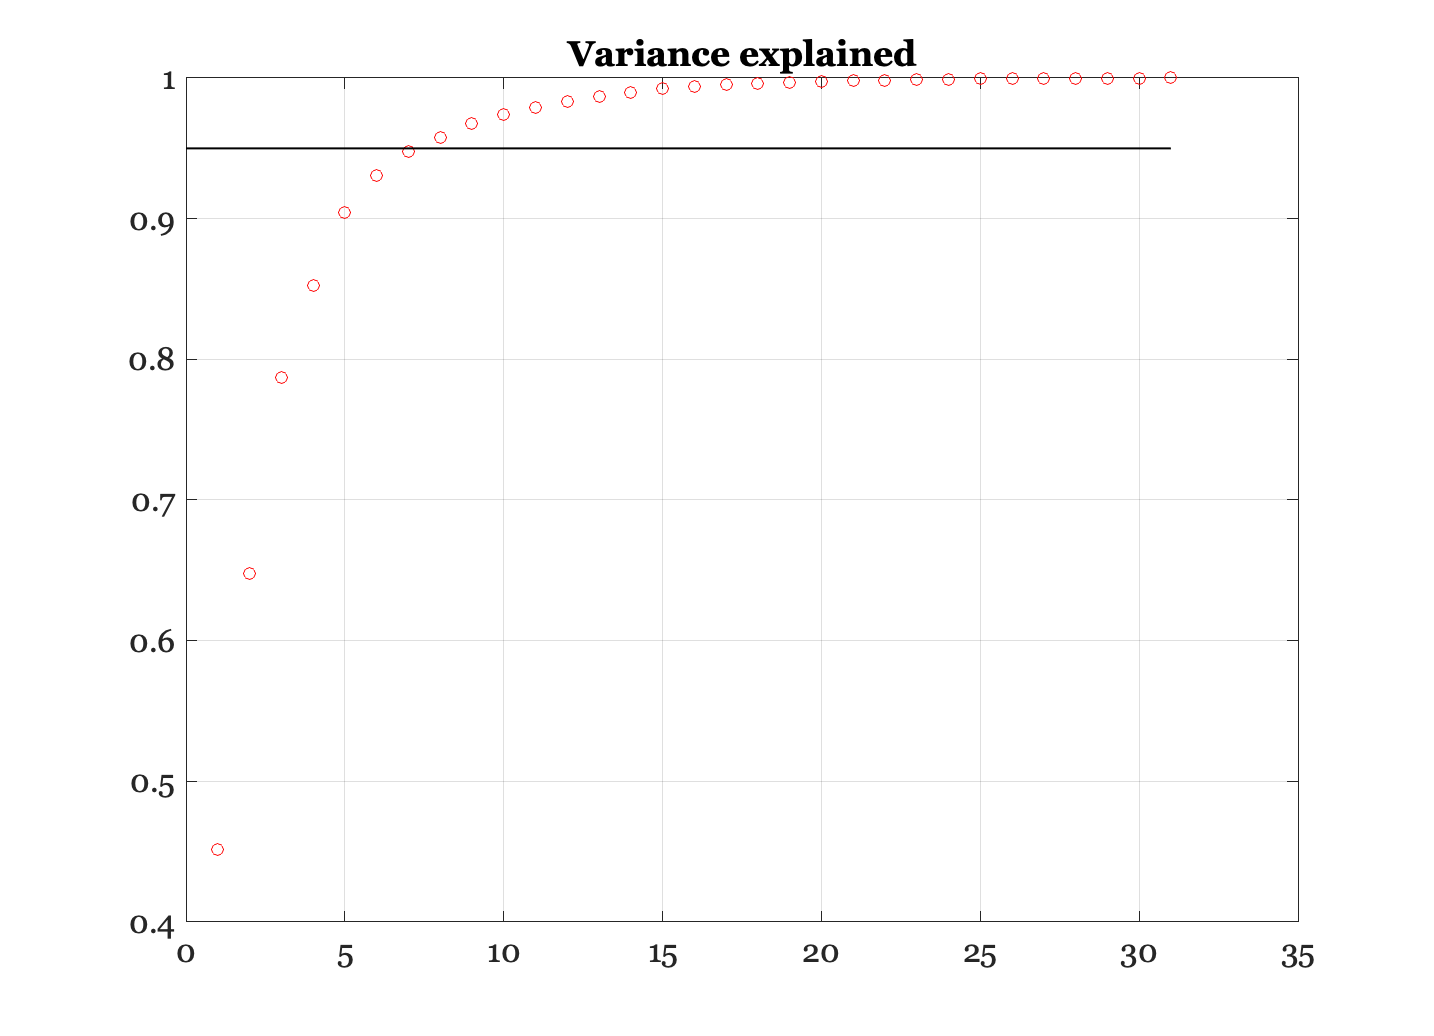

[U,D,~] = svd(radiance);
varExplained = cumsum(diag(D))/sum(D(:));

plot(varExplained,'o'); 
line([0 31],[0.95 0.95],'Color','k','LineWidth',1); 
grid on; title('Variance explained');

## Fitting a lower dimension model 

Suppose we think we should fit only a lower dimensional model.  We can choose the basis functions in different ways.  One way is to pick the first few principal components and insist that the curves be a linear sum of the those vectors.

Specifically, we choose a basis so that the spectral QE is a weighted sum.


$$spectralQE = Bw
$$


Then we solve as follows


$$rgb = Radiance'*spectralQE = Radiance'*B*w$$



$$w = (Radiance'*B)^{-1} rgb 
$$



$$spectralQE = Bw$$


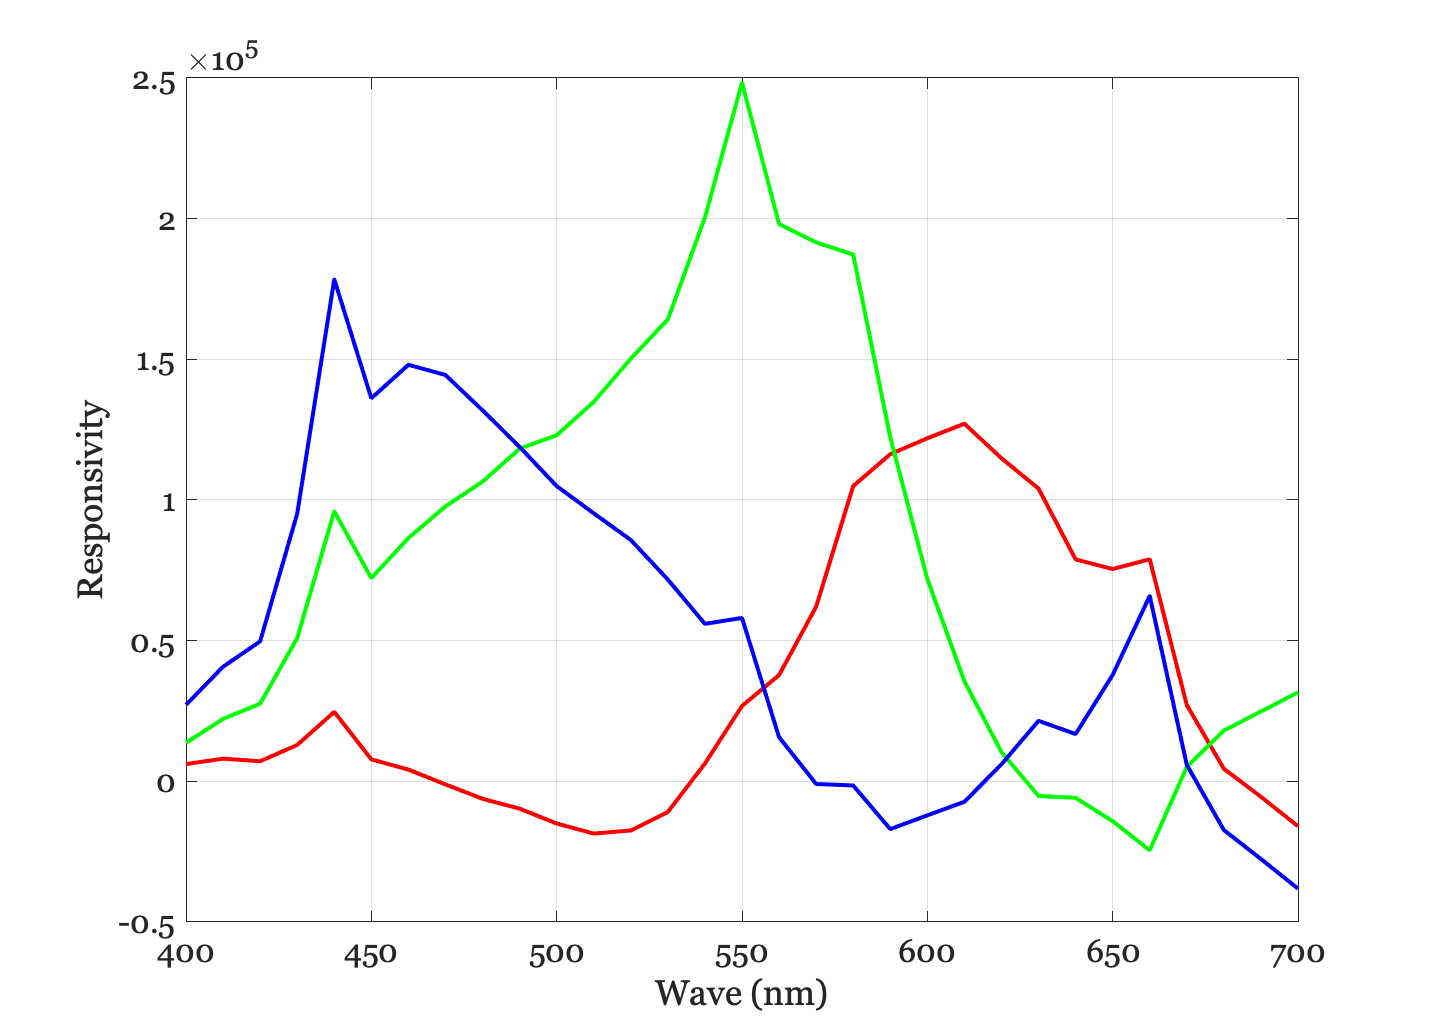

thisB = U(:,1:4);
w = pinv(radianceA'*thisB)*rgb_mean_A;
spectralQE = thisB*w;

ieNewGraphWin;
plot(wavelength,spectralQE,'LineWidth',2)
xlabel('Wave (nm)'); ylabel('Responsivity');
grid on;

How well did we do?

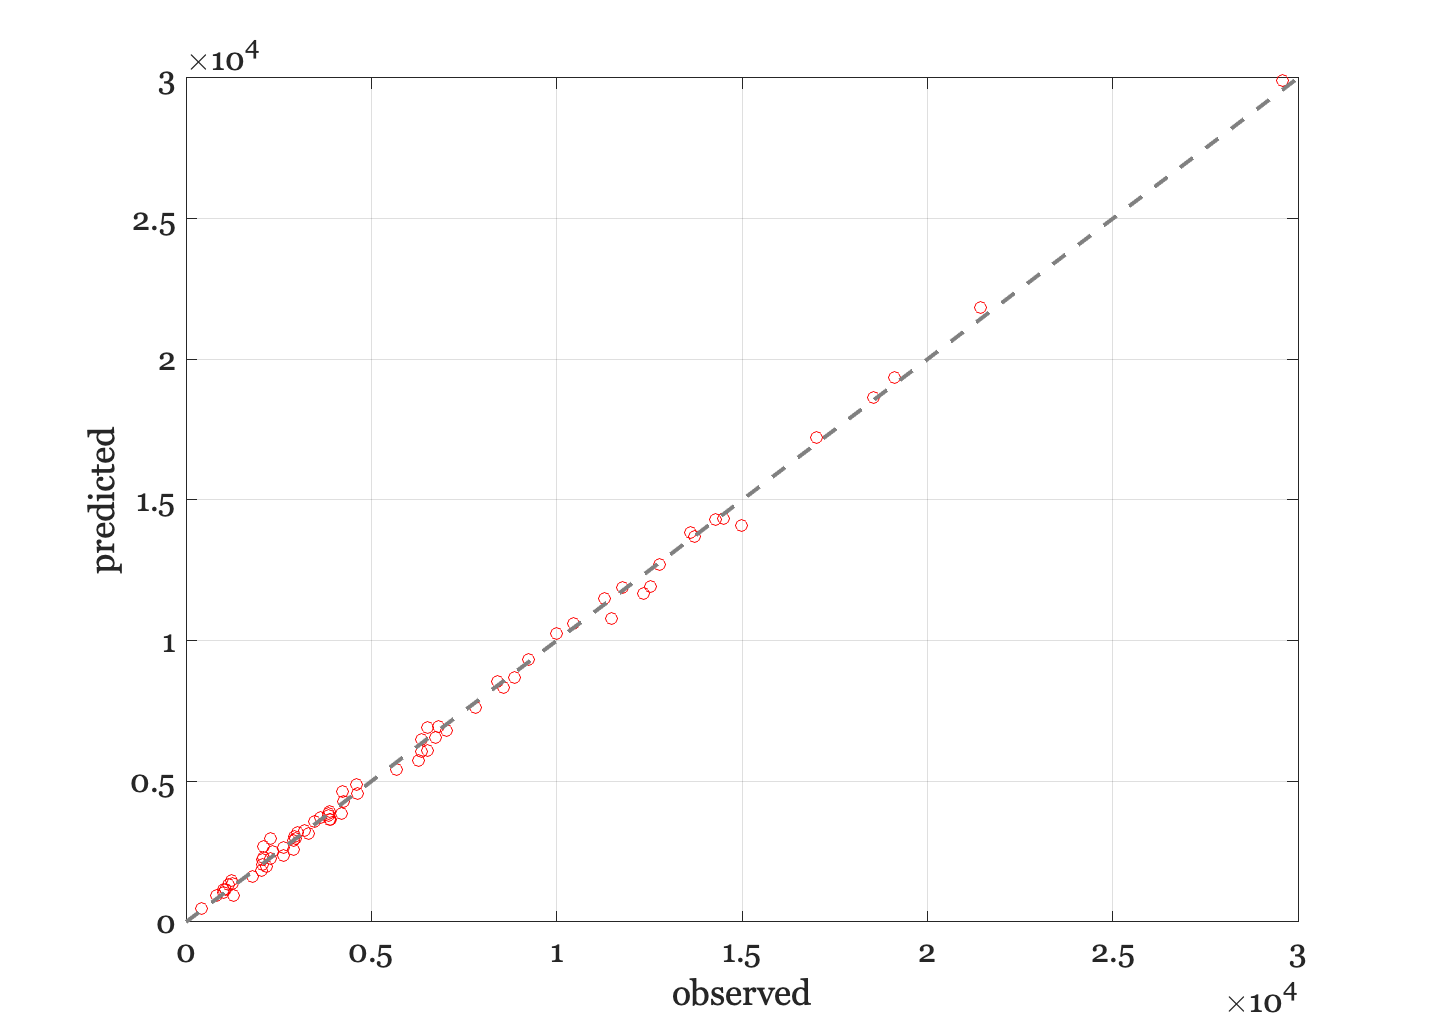

predRGB_A = radianceA'*spectralQE;
ieNewGraphWin; plot(rgb_mean_A(:),predRGB_A(:),'o');
identityLine; grid on; 
xlabel('observed');ylabel('predicted');


% The error is a few percent, about the same size (though smaller) than the
% standard deviation of the data themselves.
rms(predRGB_A(:)-rgb_mean_A(:)) / rms(rgb_mean_A(:))

ans = 0.0324

## Read sensor data for the other Illuminants

### CWF

dataDir = fullfile(teachRootPath,'local','data','spectralqe','Measurements1','DNG-Illuminant-CWF');
chdir(dataDir);
camera_cwf = 'IMG_20201024_122900.dng'; % Sensor Data under illuminant cwf taken from Canvas
thisRect = [1860  2010  370  290]; %col, row, width, height
[camera_cwf, info_cwf] = sensorDNGRead(camera_cwf,'crop',thisRect);
sensorWindow(camera_cwf);
% cpCWF = chartCornerpoints(camera_cwf);   % Select corners
% cpCWF
% {
cpCWF = [
    62   218
   337   222
   337    38
    63    37]

cpCWF =     62   218
   337   222
   337    38
    63    37


%}

blackBorder = true;  % Estimate rectangles
[rects, mLocs, pSize] = chartRectangles(cpCWF,4,6,0.5,blackBorder);

Black border


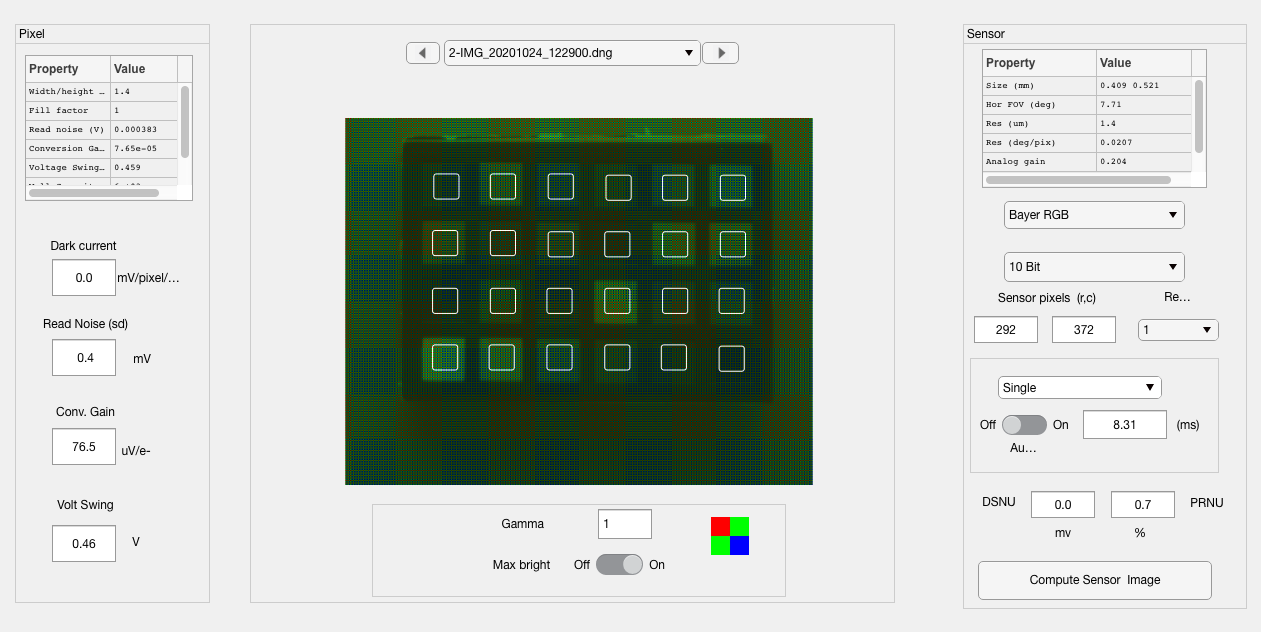

chartRectsDraw(camera_cwf,rects);  % Visualize the rectangles

nPixels = round(pSize(1)/4);  % Choose a fraction of the pixels in the patch
fullData = true;              % Return only the mean
dvalues = chartRectsData(camera_cwf,mLocs,nPixels,fullData,'dv'); %returns digital values
rgb_mean_cwf = zeros(24,3);
rgb_std_cwf  = zeros(24,3);
for ii = 1:24
    theseValues = (dvalues{ii}- info_cwf.BlackLevel(1))./info_cwf.ExposureTime;
    rgb_mean_cwf(ii,:) = nanmean(theseValues);
    rgb_std_cwf(ii,:)  = nanstd(theseValues);
end

### Daylight

dataDir = fullfile(teachRootPath,'local','data','spectralqe','Measurements1','DNG-Illuminant-Day');
chdir(dataDir);
camera_day = 'IMG_20201024_122631.dng'; % Sensor data for illuminant day taken from Canvas
thisRect = [1860  2010  370  290]; %col, row, width, height
[camera_day, info_day] = sensorDNGRead(camera_day,'crop',thisRect);
sensorWindow(camera_day);
% cpDay = chartCornerpoints(camera_day);   % Select corners
% cpDay
% {
cpDay = [
    73   218
   344   222
   344    39
    73    36];
%}
blackBorder = true;  % Estimate rectangles
[rects, mLocs, pSize] = chartRectangles(cpDay,4,6,0.5,blackBorder);

Black border


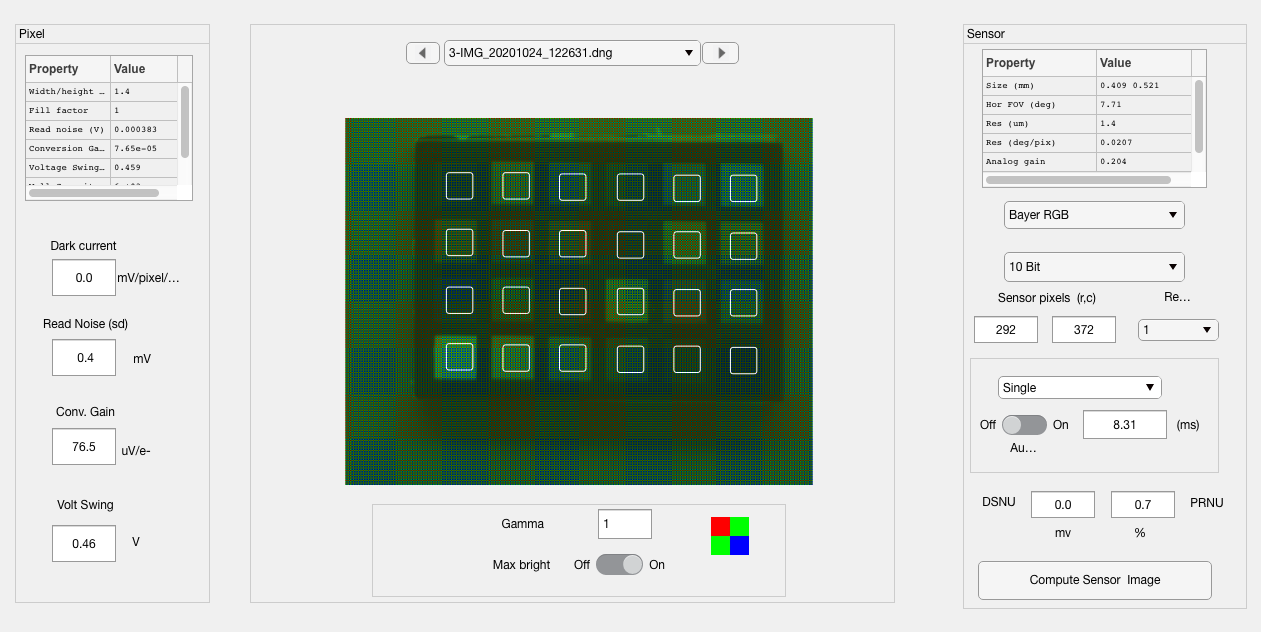

chartRectsDraw(camera_day,rects);  % Visualize the rectangles

nPixels = round(pSize(1)/4);       % Choose a fraction of the pixels in the patch
fullData = true;                   % Return only the mean
dvalues = chartRectsData(camera_day,mLocs,nPixels,fullData,'dv'); %returns digital values
rgb_mean_day = zeros(24,3);
rgb_std_day = zeros(24,3);
for ii = 1:24
    theseValues = (dvalues{ii}- info_day.BlackLevel(1))./info_day.ExposureTime;
    rgb_mean_day(ii,:) = nanmean(theseValues);
    rgb_std_day(ii,:)  = nanstd(theseValues);
end

## Put together all the RGB and radiance values and compute dimensionality

radiance = [radianceA, radianceCWF, radianceDay];
rgb_mean = [rgb_mean_A; rgb_mean_cwf; rgb_mean_day];

[U,D,V] = svd(radiance);
varExplained = cumsum(diag(D))/sum(D(:));
ieNewGraphWin;
plot(varExplained,'o'); 

line([0 31],[0.95 0.95],'Color','k','LineWidth',1); 
grid on; title('Variance explained');

## Try fitting again

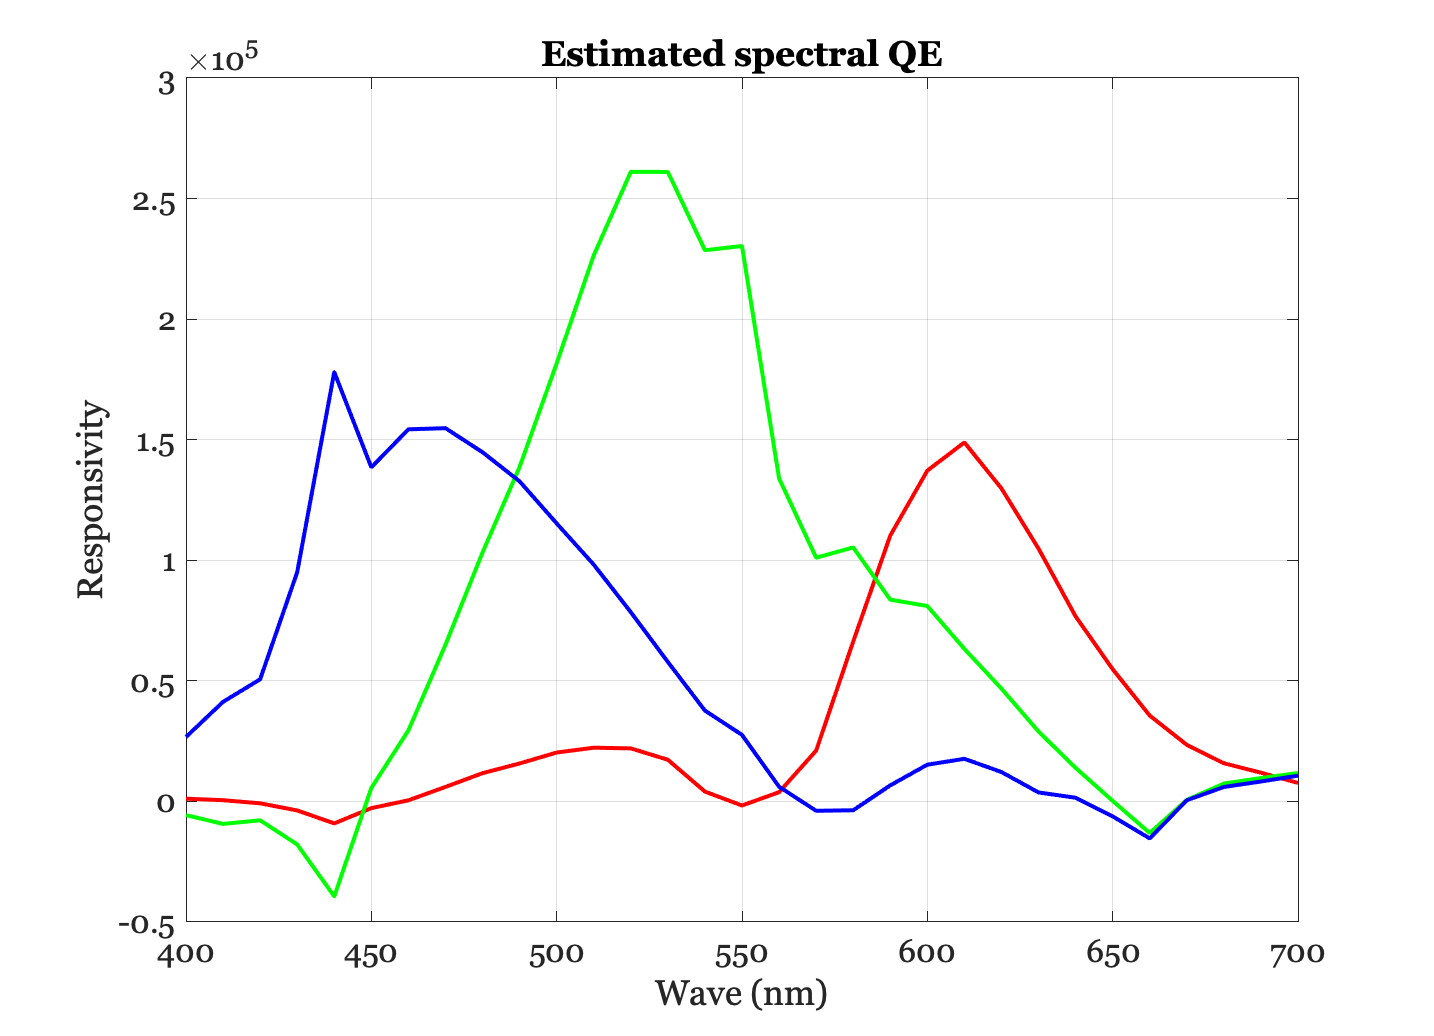

thisB = U(:,1:6);
w = pinv(radiance'*thisB)*rgb_mean;
spectralQE = thisB*w;

ieNewGraphWin;
plot(wavelength,spectralQE,'LineWidth',2)
xlabel('Wave (nm)'); ylabel('Responsivity');
grid on; title('Estimated spectral QE');

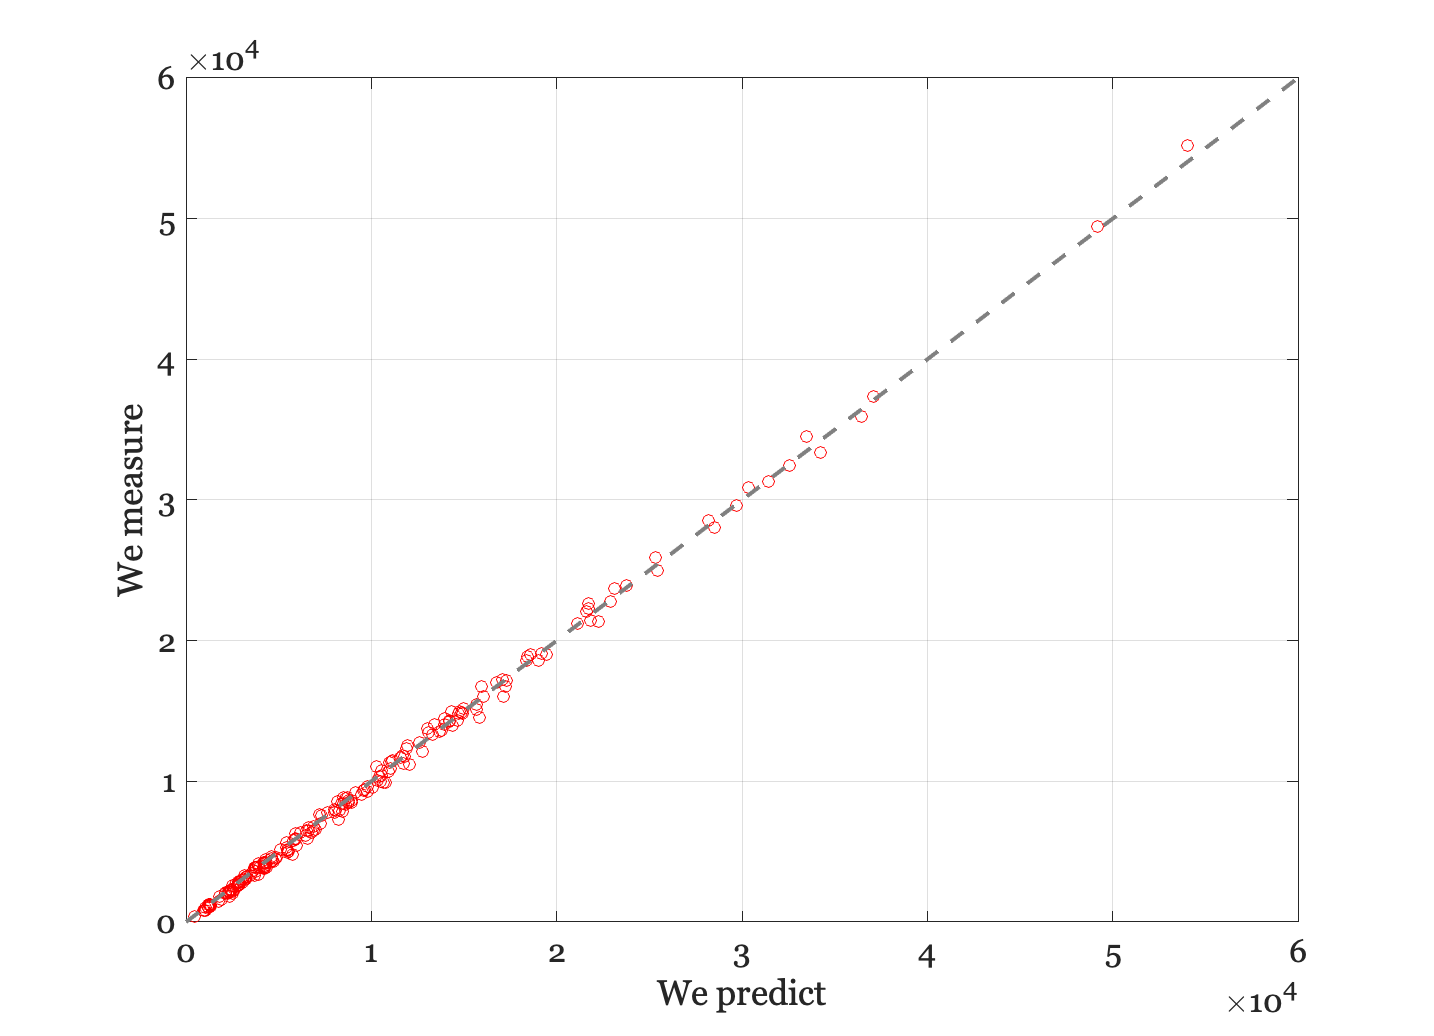


ieNewGraphWin;
predRGB = radiance'*spectralQE;
plot(predRGB(:),rgb_mean(:),'o');
identityLine; xlabel('We predict'); ylabel('We measure');

## Compare with Sony data

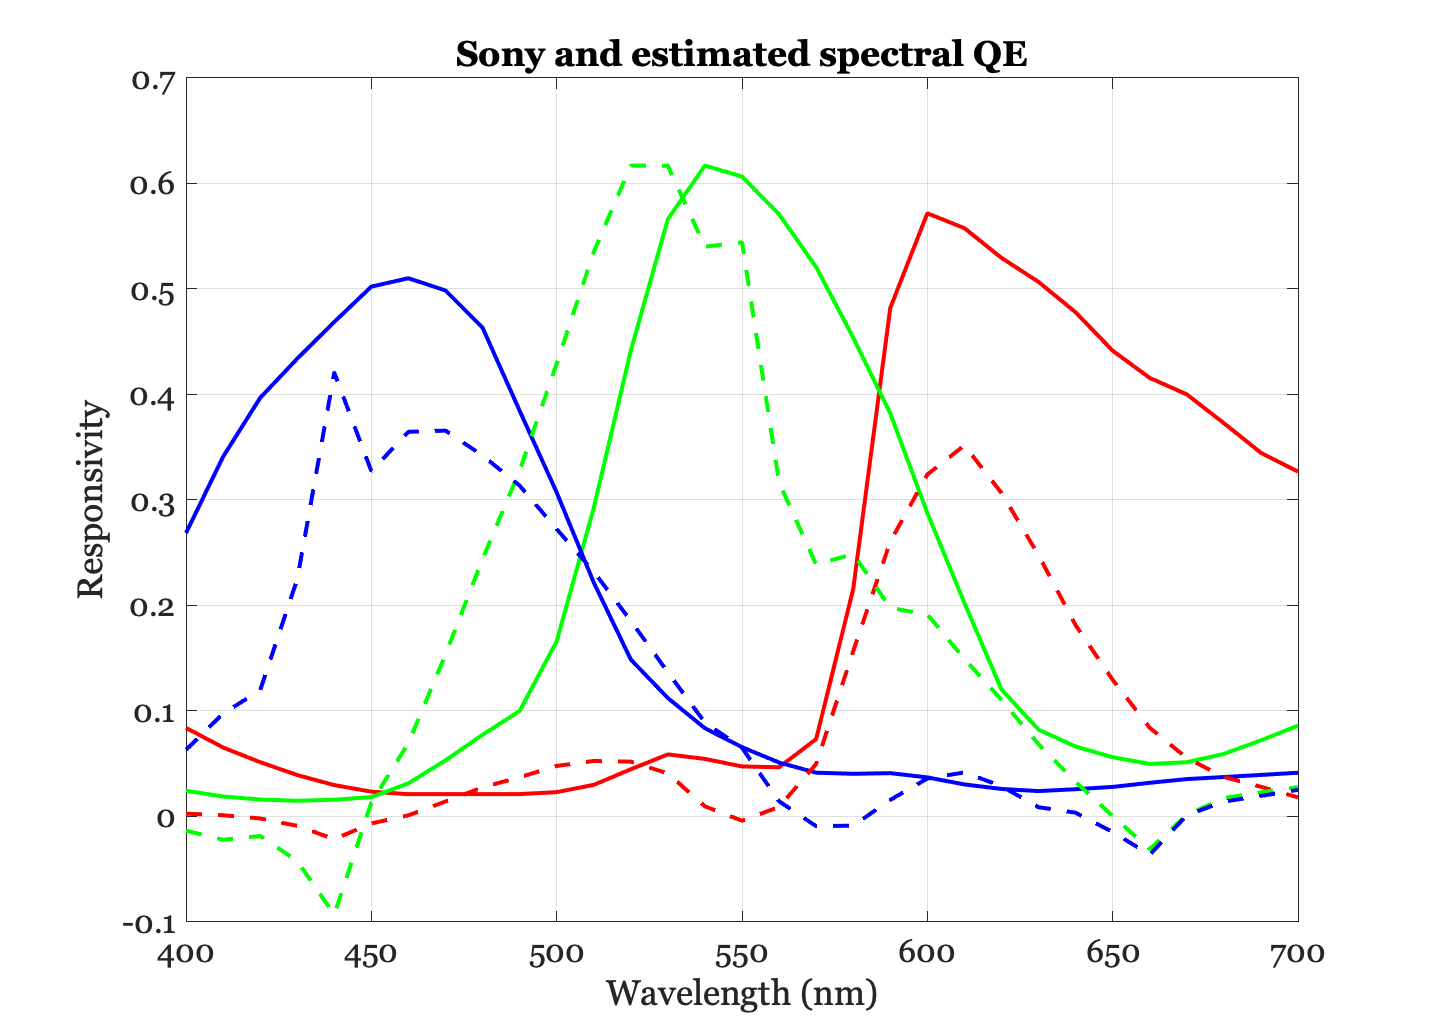

sonyQE = ieReadSpectra('qe_IMX363_public.mat', wavelength);

ieNewGraphWin;
plot(wavelength(:), sonyQE(:,1),'r',...
    wavelength(:),sonyQE(:,2),'g', ...
    wavelength(:),sonyQE(:,3),'b','LineWidth',2); 
hold on;

mx = max(sonyQE(:));
spectralQE = ieScale(spectralQE,mx);
plot(wavelength,spectralQE(:,1),'r--', ...
    wavelength,spectralQE(:,2),'g--',...
    wavelength,spectralQE(:,3),'b--','LineWidth',2);
grid on
xlabel('Wavelength (nm)'); ylabel('Responsivity')
title('Sony and estimated spectral QE')

## Compare the Sony predictions

If we just downloaded the Sony curves and used them, we would predict these RGB data.  These are not quite right, particularly the red channel.

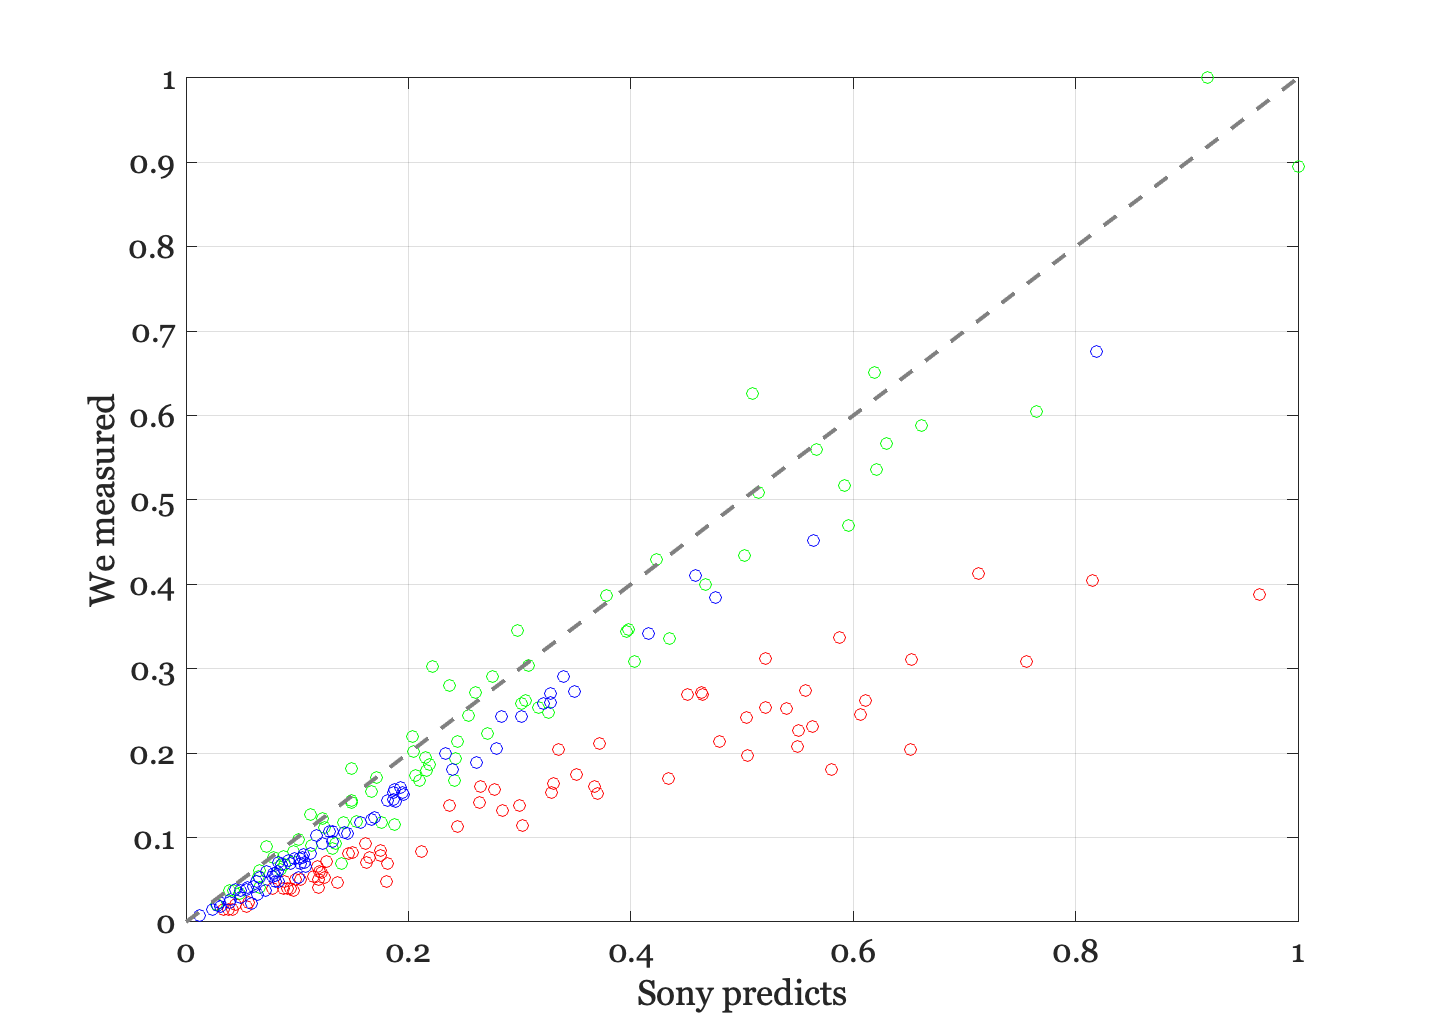

sonyRGB   = radiance'*sonyQE;
sonyRGBs  = ieScale(sonyRGB,1);

ieNewGraphWin;
plot(sonyRGBs,ieScale(rgb_mean,1),'o');
xlabel('Sony predicts'); ylabel('We measured');
grid on
identityLine;

## Best linear fit from Sony data to our estimates

Suppose we think that the implementation on the camera is like the Sony curve, but perhaps the channel gains are off, and perhaps there is some mixing between the channels.  Then we might try to fit the rgb data by using a linear transform of the Sony curves.  Let 'L' be the linear transform.


$$rgb = Radiance'*SonyQE*L$$



$$L = (Radiance'*SonyQE)^{-1} rgb$$



$$sQE = sonyQE*L$$


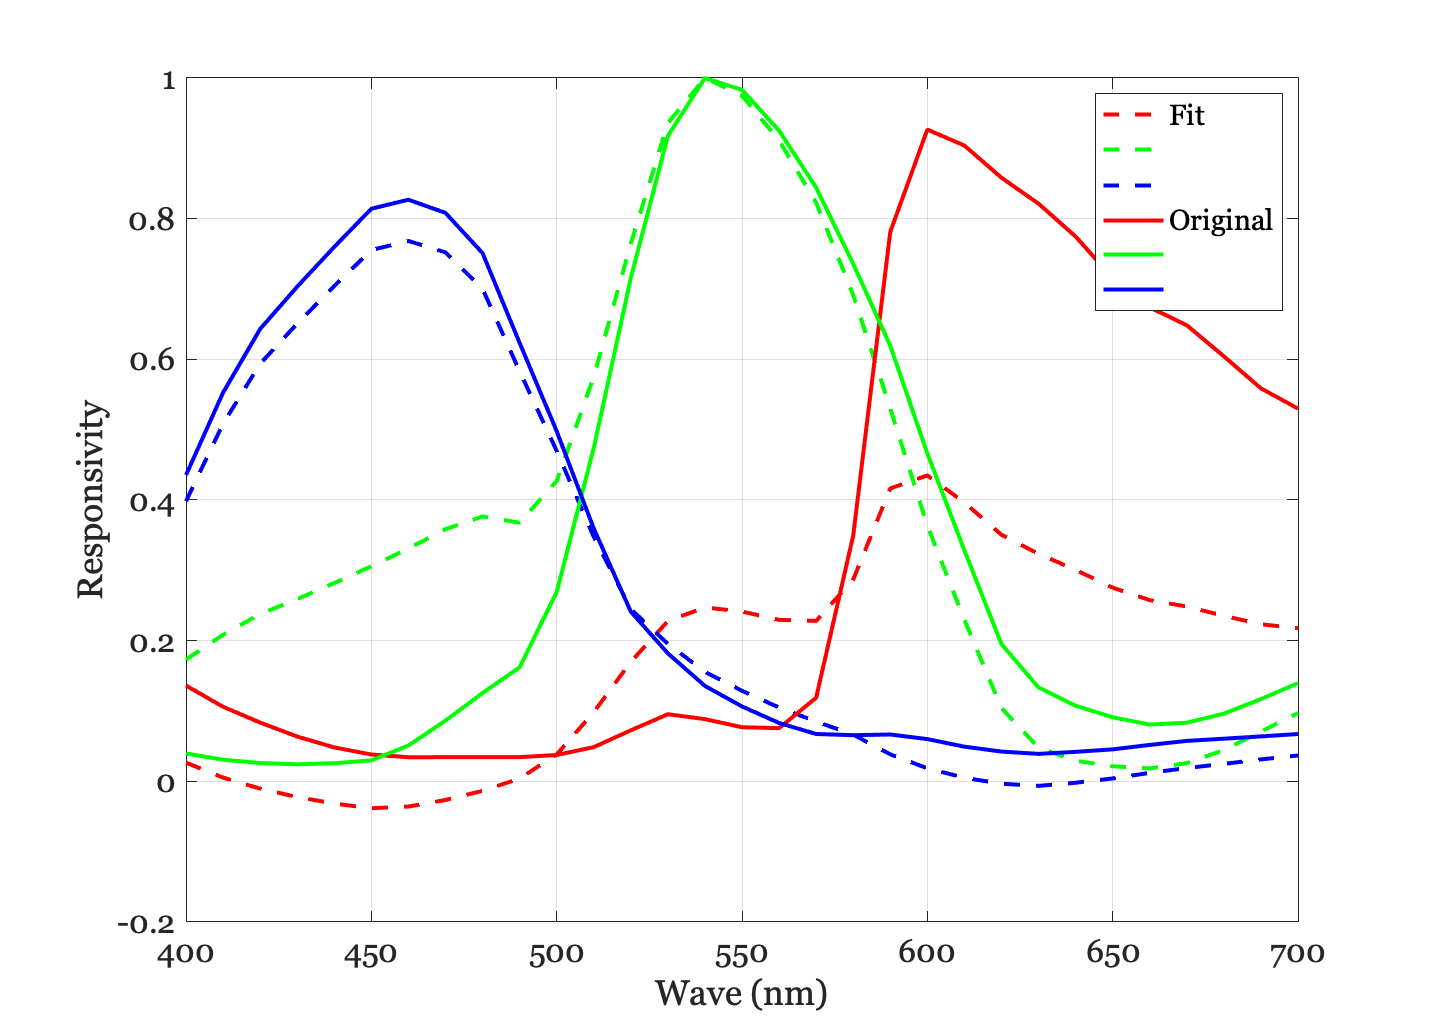

L = pinv(radiance'*sonyQE)*rgb_mean;
sQE = sonyQE*L;   % The Sony curves, transformed, to fit the data

ieNewGraphWin;
colororder({'r','g','b'}); plot(wavelength,ieScale(sQE,1),'--','LineWidth',2); hold on;
colororder({'r','g','b'}); plot(wavelength,ieScale(sonyQE,1),'-','LineWidth',2);
xlabel('Wave (nm)'); ylabel('Responsivity'); grid on;
legend({'Fit','','','Original','',''})

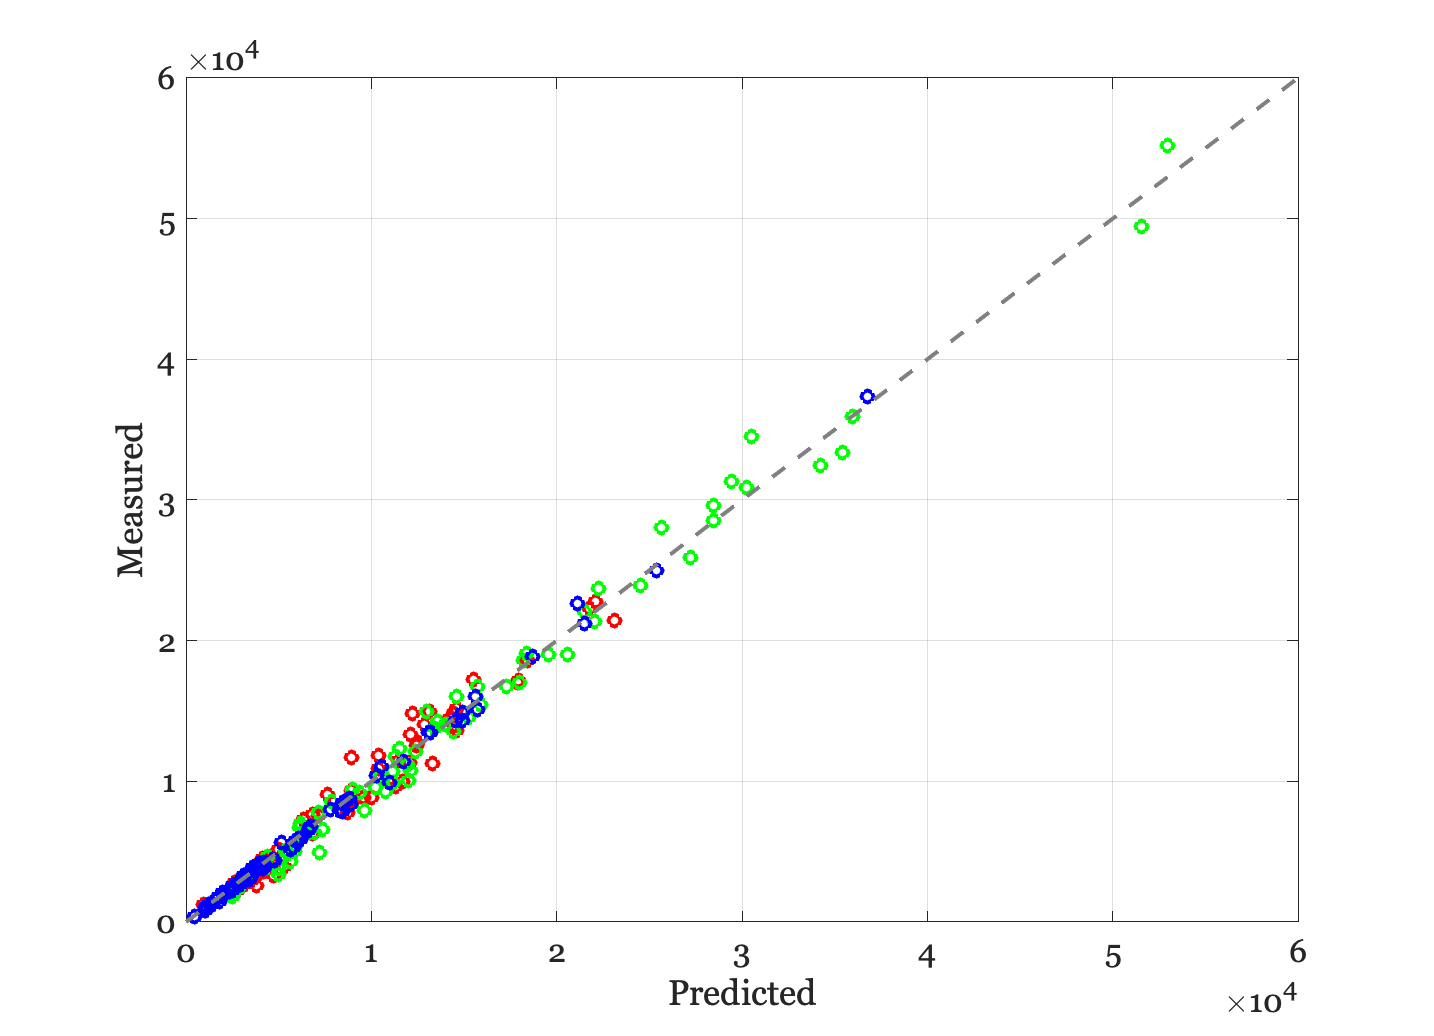


ieNewGraphWin;
predRGB = radiance'*sQE;
plot(predRGB(:,1),rgb_mean(:,1),'ro',...
    predRGB(:,2), rgb_mean(:,2),'go', ...
    predRGB(:,3), rgb_mean(:,3),'bo','LineWidth',2);
xlabel('Predicted'); ylabel('Measured'); grid on;
identityLine;